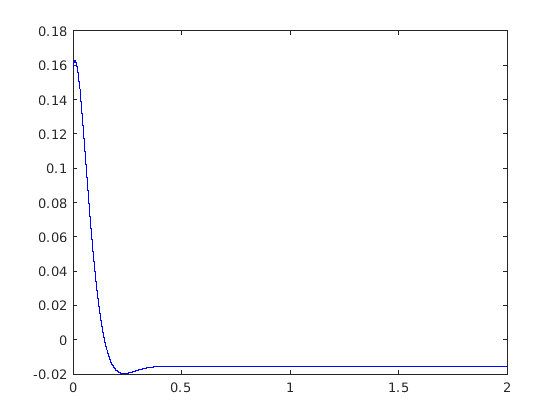

clc; clear all; close all;

m1 = 214; % kg
k1 = 100000; % N/m
L01 = 114/1000; % m
b1 = 6000; % Ns/m^1.5

k2 = 99000; % N/m
L02 = 119/1000; % m
b2 = 7100; % Ns/m^1.5

theta = deg2rad(34); % rad

h0 = 741/1000; % m
h1 = 418/1000; % m

x1 = 159/1000; % m
x1Dot = 861/1000; % m/s

g = 9.81; % m/s^2

simTime = 2; % s
t = 0; % s
dt = 10^-6; % s
idx = 1; % Counter

while(t <= simTime)
    % Calculations
    delta1 = x1 - L01;
    delta1Dot = x1Dot;
    delta2 = L02;
    delta2Dot = 0;

    Fk1 = delta1 * k1;
    Fb1 = delta1Dot * b2;
    Fk2 = delta2 * k2;
    Fb2 = delta2Dot * b2;
    Fg1 = m1*g*sin(theta);

    sumF = -Fk1-Fb1-Fk2-Fb2-Fg1;
    x1DotDot = sumF/m1;
    % F = ma
    % a = F/m
    % Logging
    t_plt(idx) = t;
    x1_plt(idx) = x1;
    x1Dot_plt(idx) = x1Dot;

    % Time integrate
    x1Dot = x1Dot + x1DotDot*dt;
    x1 = x1 + x1Dot*dt;
    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1_plt, 'b')

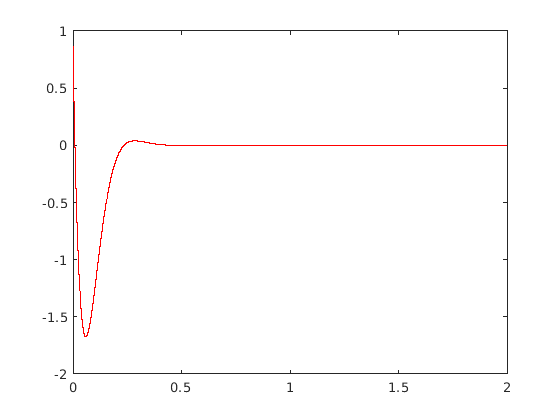

plot(t_plt, x1Dot_plt, 'r')


% What is the maximum absolute value of the velocity [mm/s] of body m1 ?
abs(max(x1Dot_plt))*1000

ans =    861


abs(min(x1Dot_plt))*1000

ans =           1674.77326692594
